### EE125 Project 4 - Circular Convolution in Matlab / Signal Compression

September 7, 2024

## Part 2: Signal Compression

Load train.wav, plot and listen to it.

[sig_train, Fs_train] = audioread('train.wav');
% soundsc(sig_train, Fs_train);
min_t_lenpow2 = 2 ^ ceil(log2(length(sig_train)))

min_t_lenpow2 = 16384

Compute FFT of the sound and plot.

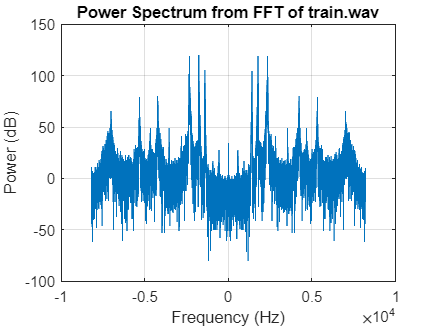

fft_t = fft(sig_train, min_t_lenpow2);
% Evenly spaced frequencies for F_t
% F_t = (0:(min_t_lenpow2 - 1)) * (Fs_train / min_t_lenpow2);
F_t = linspace(-length(fft_t)/2, length(fft_t)/2, length(fft_t));
% plot(F_t, abs(fftshift(fft_t)) .^ 2);
plot(F_t, mag2db(abs(fftshift(fft_t)) .^ 2));
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
title('Power Spectrum from FFT of train.wav');
grid on

**Question 2 -** Comment on nature of this signal. Is it dominated by a few frequencies or is energy spread across many frequencies? If you are not familiar with decibel values, you may find it useful to pick a few numbers (e.g., 1e-3, 1, 10, 1000, 1e6) and convert them to dB before answering this question so you can better interpret power when expressed in decibels.

**Answer: **I originally did not use fftshift in this part, and my answers felt like they didn't make much sense. I've redone this part with fftshift, to properly account for the frequency scale and negative frequency from FFT.

From the power spectrum, we can see that in dB which is a logarithmic scale, that the largest values occur at higher frequencies such as 1409 Hz giving 104.3 dB, 1772 Hz giving 114.3 dB, 4228.76 Hz giving 78.5 dB, 5317 Hz giving 73.6 dB, and 7022.93 Hz giving 65.7 dB. For comparison, 10 dB is 3.16 in linear, 75 dB is already 5.62 * 10^3, and 100 dB is 100,000 in linear.

What this really means is that around 1772 Hz, this high frequency has the most energy in the signal, meaning it is the most audible or loudest. Indeed, when we listen to the signal it is a high-pitched train whistle. In addition to this, there are some higher frequency overtones in the frequencies listed in the last paragraph above 1772 Hz. These frequencies are where the energy is most concentrated, as in the low frequency and beyond the overtowns, the graph is mostly around 0 dB.

The "poor cropping" of the chart resulted from using the minimum power of two length for the FFT, essentially zero-padding only for log efficiency, not accuracy.

**Testing Functions from Questions 3 and 4**

test_fftcomp = FFTcompression(sig_train, 100);
F_test = linspace(-length(test_fftcomp)/2, length(test_fftcomp)/2, length(test_fftcomp));
% plot(F_test, abs(test))
% plot(F_test, mag2db(abs(fftshift(test))))
% plot(F_test, ifft(test_fftcomp, length(sig_train)))
% soundsc(ifft(test_fftcomp), Fs_train) % it works pretty well!

test_recon = ifft(FFTcompression(sig_train, 1));
test_snr = SNRoverall(sig_train, test_recon)

test_snr = 10.3395

**Question 5: **Call the above functions to get the compressed spectra for percentRetained equal to 100, 50, 20, and 10. For each, save the output spectra in the workspace (for example Sc100, Sc50, etc). For each, reconstruct the signal using ifft, and save the results in other variables called, for example, recon100, recon50, etc.

% Compressed Spectra
Sc100   = FFTcompression(sig_train, 100);
Sc50    = FFTcompression(sig_train, 50);
Sc20    = FFTcompression(sig_train, 20);
Sc10    = FFTcompression(sig_train, 10);

% Reconstructed Signals
recon100 = ifft(Sc100);
recon50  = ifft(Sc50);
recon20  = ifft(Sc20);
recon10  = ifft(Sc10);

% Playback
% soundsc(recon100, Fs_train)
% soundsc(recon10, Fs_train)

- Listen to the sounds. Does the compression hurt the sound quality much? If not, how far can you push things and still have a recognizable signal (can you discard >90% of the components?)

**Answer: **To be honest, no, the compression doesn't hurt the sound quality that much, especially when it comes to still having a recognizable signal. I thought back to the time in lecture where you compressed an audio file of you speaking to only 1 and 0 bits, and it was surprisingly audible. I tried all the way to 1% retained and I can still recognize it is a train whistle. Of course, in the background, the lower the percent retained, the larger the frequency bin's amplitude needs to be so that it is retained.

- Make a plot showing the original magnitude spectrum for train.wave in blue (basically, the plot you made in Step 2, but overlay on top of it the power spectrum Sc10 (the spectrum with the 10% retained) in red. Can you relate this plot to the quality (or lack thereof) in the reconstructed sound?

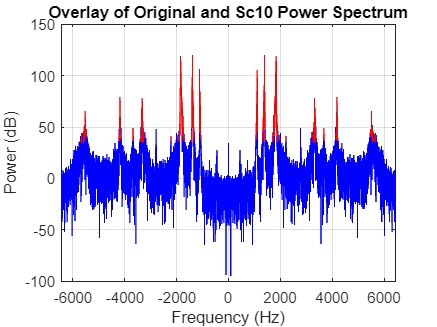

fft_t_comp = fft(sig_train, length(sig_train));
plot(F_test, mag2db(abs(fftshift(fft_t_comp)) .^ 2), 'blue');
hold on
plot(F_test, mag2db(abs(fftshift(Sc10) .^ 2)), 'red');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
title('Overlay of Original and Sc10 Power Spectrum');
grid on
hold off

**Answer:** We see from the overlaid plot that indeed, our compression is doing a great job by cutting out frequency bins that aren't contributing the most to the signal. Previously, we identified that the characteristic of the sound is defined by the highest energy frequency bins, which is the high frequency around 1772 Hz with additional overtones. Indeed, the Sc10 power spectrum contrains only those 5 main bins

This gives reason as to why only so little of the signal needs to be retained (10% wow!) for it to still be recognizable. However, I would assume for a signal with a wider range of bins with large amounts of energy (eg. complicated song mix), that compression will have a greater effect on the recognizability of the output.

-  Compute and tabulate the SNR for each reconstructed signal.

**Answer:**

snr100  = SNRoverall(sig_train, recon100)

snr100 = 307.7107

snr50   = SNRoverall(sig_train, recon50)

snr50 = 35.7987

snr20   = SNRoverall(sig_train, recon20)

snr20 = 28.2415

snr10   = SNRoverall(sig_train, recon10)

snr10 = 24.5764

            |    recon100    |    recon50    |    recon20    |    recon10

SNR    |    307.7107    |    35.7987    |    28.2415    |    24.5764

**Question 6: **Now, clear all variables from the workspace and load onscreen.wav. Repeat Step 5. How do the characteristics of the various signals affect the amount of compression possible?

- Listen to the sounds. Does the compression hurt the sound quality much? If not, how far can you push things and still have a recognizable signal (can you discard >90% of the components?)

**Answer:** The compression impacts the sound quality a lot more for the onscreen.wav audio. Now, it is still recognizable, "on screen" is entirely understandable and the three beeps are still audble even at Sc10. So even when 90% of the components are discarded, the signal is still recognizable. However, compared to the train whistle, the characteristic is worse from a subjective standpoint. My reasoning is that Captain Picard's vocal register is quite low, but with human speech, there still remains a mid/high frequency component that makes the overall voice sound "whole". The compression takes away the mid/high frequencies as the amplitude or energy in those bins are significantly less, with a "less so" exception of the frequencies at which the beeps occur.

- Make a plot showing the original magnitude spectrum for train.wave in blue (basically, the plot you made in Step 2, but overlay on top of it the power spectrum Sc10 (the spectrum with the 10% retained) in red. Can you relate this plot to the quality (or lack thereof) in the reconstructed sound?

**Answer:** Pasted image here due to .mlx file. The Sc10 overlaid on the original power spectrum gives credit to my previous explaination that the signal quality is subjectively worse than the train whistle sound. The retained signal is centered around the low frequencies, corresponding to Captain Picard's lower register.

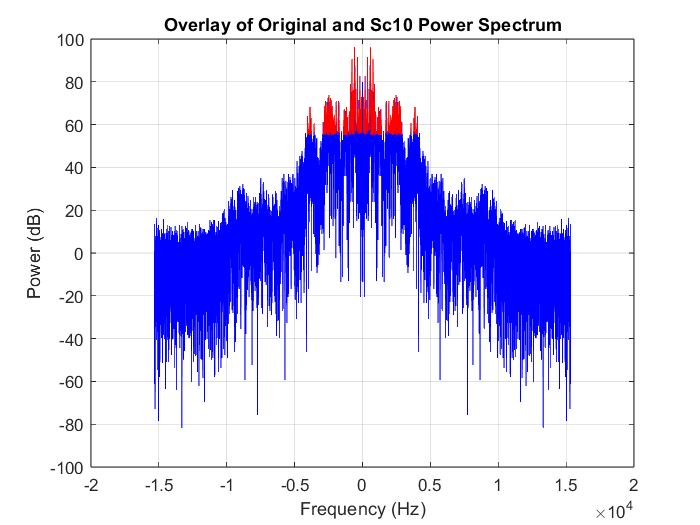

- Compute and tabulate the SNR for each reconstructed signal

            |    recon100    |    recon50    |    recon20    |    recon10

SNR    |    300.8448    |    28.0004    |    16.1544    |    9.4121

**Answer: **In signal-to-noise ratios, higher is better, as it means more sound is represented over noise. We see here that the compression results in more noise and a worse SNR when compared to the train whistle signal.

**Storage Savings Due to Compression**

**Question 1 - **Compare the original signal to any of the frequency-domain version (Sc100, Sc50, etc). You should see that the FFT appears to have doubled your storage requirements. Is that really true? If you were going to save these variables to disk, how can you use your knowledge of Fourier transform properties to save storage? Would the amount of memory to store the frequency-domain signal be bigger, smaller, or the same as storing the time-series data, and why?

whos Sc10

  Name          Size             Bytes  Class     Attributes

  Sc10      12880x1             206080  double    complex   



whos sig_train

  Name               Size             Bytes  Class     Attributes

  sig_train      12880x1             103040  double              



**Answer:** While the bytes needed to store any of the frequency-domain versions is indeed doubled, I assume that it is not only storing the values as complex. That alone would contribute to a possible size increase if the implementation of complex numbers differs from typical floating point or integer values. The other reason for size difference is that MATLAB might not be taking advantage of conjugate symmetry to store the signal.

Knowing conjugate symmetry, we can save half of the spectrum as the other half is symmetrically identical, which in theory would mean cutting the number of bytes saved in half (assuming MATLAB is saving everything). This would be the same size as the time-series data, as it is currently double the time-series data size.

**Question 2 - **Now, compare the no-compression version of the spectrum (Sc100) to the 90% compressed (Sc10). You should see that the storage used for both is the same even though 90% of the values in Y10 are zero! The reason for this is that, so far, we are not being very clever — we are storing the number ‘0’ in each of the discarded FFT bins.

A better approach is to store a) only the non-zero values and b) a list of which frequency bin corresponds to each non-zero value. Because this is a common need, some computer languages have built-in data types to store this type of data. In Matlab and Python, the data type is known as a ‘sparse’ array (i.e., mostly zero).

Look at the Matlab LiveScript playWithSparse.mlx or the Python code playWithSparse.py that is provided with the assignment. It should give you an idea how sparse arrays work. Investigate this using the following:

Define a sparse array Ssp which is the same size as Sc10. Assign only the non-zero values of Sc10 to Ssp. How do the sizes of Ssp and Sc10 compare? You should see a substantial savings. Since Ssp only contains 10% of the entries of Sc10, you might thing the size would be exactly 10x smaller. Is that true? If not, can you explain why?

Ssp = sparse(Sc10)

Ssp =    1.0e+02 *

      (1061,1)           -0.0093 - 0.1030i
      (1064,1)           -0.0113 - 0.1136i
      (1066,1)            0.0698 - 0.0699i
      (1067,1)            0.0098 - 0.1723i
      (1068,1)           -0.0794 - 0.0345i
      (1069,1)            0.1418 - 0.0472i
      (1070,1)           -0.0122 - 0.2216i
      (1072,1)            0.2004 - 0.0457i
      (1073,1)            0.0167 - 0.2762i
      (1074,1)           -0.0938 + 0.0510i
      (1075,1)            0.2095 - 0.0043i
      (1076,1)            0.0478 - 0.3100i
      (1077,1)           -0.1218 - 0.0010i
      (1078,1)            0.2683 + 0.0232i
      (1079,1)            0.1582 - 0.2738i
      (1080,1)           -0.0794 - 0.0510i
      (1081,1)            0.1815 + 0.0659i
      (1082,1)            0.2691 - 0.1467i
      (1083,1)            0.1146 - 0.1287i
      (1085,1)            0.2070 + 0.1883i
      (1086,1)            0.4141 - 0.0390i
      (1087,1)           -0.1266 - 0.2276i
      (1088,1)           -0.1669 +

whos Sc10

  Name          Size             Bytes  Class     Attributes

  Sc10      12880x1             206080  double    complex   



whos Ssp

  Name          Size            Bytes  Class     Attributes     

  Ssp       12880x1             30928  double    sparse, complex



206080 / 30928

ans = 6.6632

**Answer:** The size of Sc10 is 206080 Bytes, wheras Ssp is 30928 Bytes. This means Ssp is almost 7 times smaller in size. I did expect something closer to 10 times, but the difference could be due to whatever encoding method MATLAB chose to use on how to place the zeros.

**Discrete Cosine Transform**

**Question 1 - **Set up a vector D which is all zeros, and is 1024 samples long. Then do the following:

D = zeros(1024, 1);

- Set D(1)=1, then take the inverse DCT using idct and plot the result.

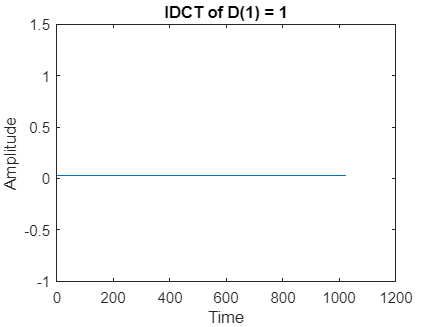

D(1) = 1;
d = idct(D);
plot(linspace(0, length(d), length(d)), d)
xlabel('Time')
ylabel('Amplitude')
title('IDCT of D(1) = 1')

- Reset D(1)=0, then set D(2)=1 and repeat the last step

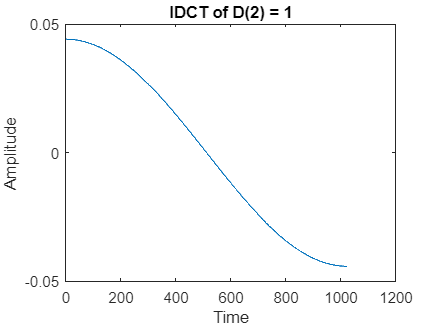

D(1) = 0;
D(2) = 1;
d = idct(D);
plot(linspace(0, length(d), length(d)), d)
xlabel('Time')
ylabel('Amplitude')
title('IDCT of D(2) = 1')

- Reset D(2)=0, then set D(3)=1 and repeat

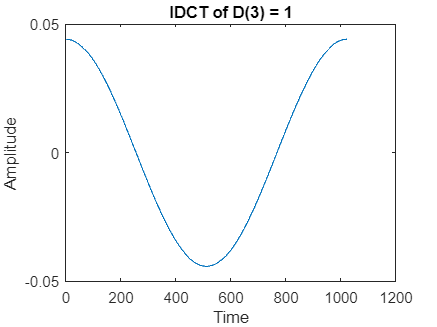

D(2) = 0;
D(3) = 1;
d = idct(D);
plot(linspace(0, length(d), length(d)), d)
xlabel('Time')
ylabel('Amplitude')
title('IDCT of D(3) = 1')

- In your report, include the 3 plots and discuss how you can explain the results in terms of the idct documentation.

**Answer:** The idct documentation shows that a sinusoid is assumed. Given the fact we present it with a frequency response at a particular frequency, such as at w=0 for the first plot, w=1 for the second, and w=2 for the third, we see that where w is controls the periodicity of the resulting idct. The higher the value the 1 is at, the faster the period.

**Question 2 - **See functions below for DCTcompression.

**Question 3 -** Now, let’s compare DCT- and FFT-based compression. When you do so, use the onscreen.wav sound f ile. Call the above functions to get the compressed spectra for 100, 50, 20, and 10. For each, save the output spectra in the workspace (for example Dc100, Dc50, etc). For each, reconstruct the signal using idct and save the results in other variables called for example dctRecon100, dctRecon90, etc.

- Compute and tabulate the SNR for each reconstructed signal. You should find that DCT compression gets slightly better SNR than FFT.

% Compressed Spectra (it says sig_train, but it was done with onscreen.wav)
Dc100   = DCTcompression(sig_train, 100);
Dc50    = DCTcompression(sig_train, 50);
Dc20    = DCTcompression(sig_train, 20);
Dc10    = DCTcompression(sig_train, 10);

% Reconstructed Signals
dctRecon100 = idct(Dc100);
dctRecon50  = idct(Dc50);
dctRecon20  = idct(Dc20);
dctRecon10  = idct(Dc10);

% Playback (again, done with onscreen.wav)
% soundsc(recon20, Fs_train)
% soundsc(dctRecon20, Fs_train)

% SNR
DCTsnr100  = SNRoverall(sig_train, dctRecon100)

DCTsnr100 = 307.6192

DCTsnr50   = SNRoverall(sig_train, dctRecon50)

DCTsnr50 = 38.5977

DCTsnr20   = SNRoverall(sig_train, dctRecon20)

DCTsnr20 = 29.6160

DCTsnr10   = SNRoverall(sig_train, dctRecon10)

DCTsnr10 = 25.6350

            |    dctRecon100    |    dctRecon50    |    dctRecon20    |    dctRecon10

SNR    |    301.6054          |    30.3283           |    18.2083          |    11.3832

It seems like the overall SNR is slightly improved when compared to the recovered signal from the FFT-based compression.

- Listen to the DCT vs. FFT-based compression with 20% of coefficients retained. You should be able to hear a slight difference, though probably not dramatic.

**Answer: **The noise sounds less harsh and the compression is less noticable, it sounds more "smoothed" than anything.

*Thank you for reading! End of part 2 and project 4!*

**Function Definitions Below.**

For FFTcompression.

function Sc = FFTcompression(signal, percentRetained)
    fft_temp = fft(signal, length(signal));
    amp_bins = abs(fft_temp);
    sorted_amp_bins = sort(amp_bins);
    fft_length = length(fft_temp);
    if eq(percentRetained, 0)
        Sc = zeros(fft_length, 1);
        return
    end
    threshold_index = floor((1 - percentRetained / 100) * (length(fft_temp))) + 1;
    threshold_amp = sorted_amp_bins(threshold_index);
    bin_index = 1;
    last_bin_index = length(amp_bins);
    while bin_index <= last_bin_index
        if amp_bins(bin_index) < threshold_amp
            fft_temp(bin_index) = 0;
        end
        bin_index = bin_index + 1;
    end
    Sc = fft_temp;
end

For SNROverall

function snr = SNRoverall(signal, reconSignal)
    num = sum(signal .^ 2);
    denom = sum((signal - reconSignal) .^ 2);
    if eq(denom, 0)
        snr = 0;
        return
    end
    snr = 10 * log10(num / denom);
end

For DCTcompression.

function Dc = DCTcompression(signal, percentRetained)
    dct_temp = dct(signal, length(signal));
    amp_bins = abs(dct_temp);
    sorted_amp_bins = sort(amp_bins);
    dct_length = length(dct_temp);
    if eq(percentRetained, 0)
        Dc = zeros(dct_length, 1);
        return
    end
    threshold_index = floor((1 - percentRetained / 100) * (length(dct_temp))) + 1;
    threshold_amp = sorted_amp_bins(threshold_index);
    bin_index = 1;
    last_bin_index = length(amp_bins);
    while bin_index <= last_bin_index
        if amp_bins(bin_index) < threshold_amp
            dct_temp(bin_index) = 0;
        end
        bin_index = bin_index + 1;
    end
    Dc = dct_temp;
end